## 实值符号差错模型

### 参数设置

clearvars;
close all;
clc;
rng(2023);  %固定随机种子，保证结果可复现

% 参数
% 信噪比范围 E_s/σ^2
snr_dB = -5:1:20;           %给定了信噪比范围：-5~20dB
snr = 10.^(snr_dB/10);      %信噪比的常数标识

% 符号数
M = [2;4];

% 重复实验次数，可修改
N = 1e4;

### 计算

% 随机生成符号序列
%是两个2×26的矩阵，分别对应2个M和26个SNR
ber = zeros(length(M),length(snr));
ser = zeros(length(M),length(snr));
for cnt1 = 1:length(M)
    % 生成bit序列（bit_data）
    if M(cnt1)==2
        bit_data = randi([0 1], 1, N); % N个bit，N个符号
    elseif M(cnt1)==4
        bit_data = randi([0 1], 1, 2*N); % 2N个bit，N个符号
    else
        error('Invalid modulation order');
    end

    % 转化为符号映射后的离散符号序列（mod_data）
    if M(cnt1)==2
        mod_data = my_gray_map_real_M2(bit_data);
    elseif M(cnt1)==4
        mod_data = my_gray_map_real_M4(bit_data);
    end

    % 发送端平均符号能量
    Es = sum(mod_data.^2)/N;
    % 理论平均符号能量
    Es_theory = (M(cnt1)^2-1)/3;

    for cnt2 = 20:20
        % 加性噪声
        noise_power = Es/snr(cnt2);
        noise = normrnd(0,sqrt(noise_power),size(mod_data));

        % 加性高斯噪声信道，获得接收信号（rx_data）
        rx_data = mod_data + noise;

        % 解调，根据离散符号序列获得bit序列（demod_bit_data）
        if M(cnt1)==2
            demod_bit_data = my_inverse_gray_map_real_M2(rx_data);
        elseif M(cnt1)==4
            demod_bit_data = my_inverse_gray_map_real_M4(rx_data);
        end

        % 差错比特
        bit_err = xor(bit_data, demod_bit_data);
        % 计算差错比特数
        ber(cnt1,cnt2) = sum(bit_err);
        % 计算差错符号数
        if M(cnt1) == 2
            ser(cnt1,cnt2) = ber(cnt1,cnt2);
        elseif M(cnt1) == 4
            bit_err = reshape(bit_err,[],N);
            ser(cnt1,cnt2) = sum(bit_err(1,:) | bit_err(2,:));
        end
    end
end

% 误码率和误比特率归一化
% ber = ber./(N*([1;2]*ones(1,26)));%误比特率的M4情况对不上
% ser = ser./N;

% 理论值
ser_theory = (2*(M-1)./M)*ones(1,26).*qfunc(sqrt(3./(M.^2-1)*snr));
ber_theory = ser_theory./log2(M);

### 绘图

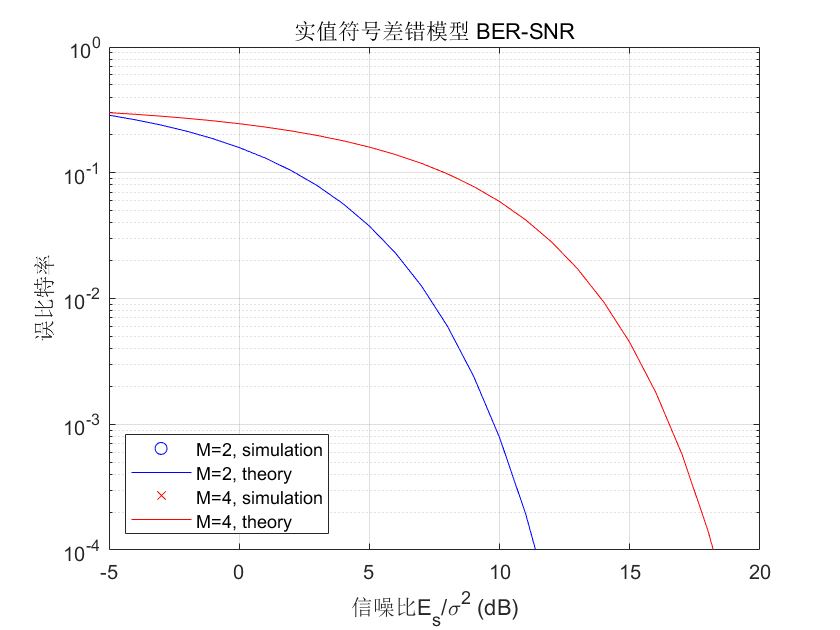

% 绘图
figure;
semilogy(snr_dB, ber(1,:),'bo', ...
    snr_dB, ber_theory(1,:),'b', ...
    snr_dB, ber(2,:),'rx', ...
    snr_dB, ber_theory(2,:),'r');
xlabel('信噪比E_s/\sigma^2 (dB)');
ylabel('误比特率');
set(gca, 'ylim', [1e-4,1e0]);
legend('M=2, simulation', 'M=2, theory', ...
    'M=4, simulation', 'M=4, theory', ...
    'Location', 'southwest');
title('实值符号差错模型 BER-SNR');
box on;
grid on;

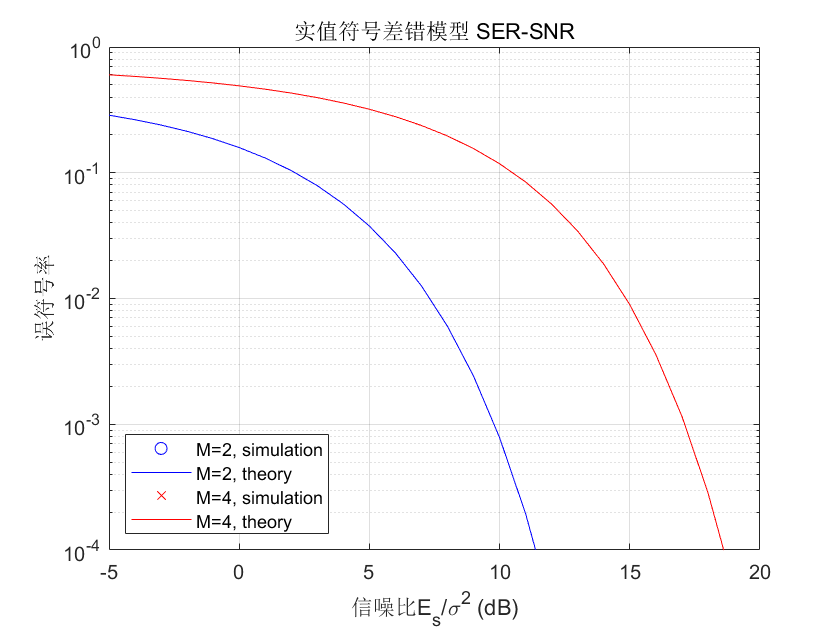


figure;
semilogy(snr_dB, ser(1,:),'bo', ...
    snr_dB, ser_theory(1,:),'b', ...
    snr_dB, ser(2,:),'rx', ...
    snr_dB, ser_theory(2,:),'r');
xlabel('信噪比E_s/\sigma^2 (dB)');
ylabel('误符号率');
set(gca, 'ylim', [1e-4,1e0]);
legend('M=2, simulation', 'M=2, theory', ...
    'M=4, simulation', 'M=4, theory', ...
    'Location', 'southwest');
title('实值符号差错模型 SER-SNR');
box on;
grid on;

### 格雷映射函数

实值符号差错模型，M=2，由bit序列映射到离散符号

function mod_data = my_gray_map_real_M2(bit_data)
% 对应的符号序列长度
N = length(bit_data);
mod_data = zeros(1,N);
% 逐个符号判断映射关系
for n = 1:N
    current_bits = bit_data(n);
    if current_bits == 0
        mod_data(n) = -1 ;
    elseif current_bits == 1
        mod_data(n) = 1 ;
    end
end
end

 实值符号差错模型，M=4，由bit序列映射到离散符号

function mod_data = my_gray_map_real_M4(bit_data)
if mod(length(bit_data),2)==0
    % 对应的符号序列长度
    N = length(bit_data)/2;
    mod_data = zeros(1,N);
    % 逐个符号判断映射关系
    for n = 1:N
        current_bits = bit_data(2*n-1 : 2*n);
        if current_bits(1)==0 && current_bits(2)==0
            mod_data(n) = -3 ;
        elseif current_bits(1)==0 && current_bits(2)==1
            mod_data(n) = -1 ;
        elseif current_bits(1)==1 && current_bits(2)==1
            mod_data(n) = 1 ;
        elseif current_bits(1)==1 && current_bits(2)==0
            mod_data(n) = 3 ;
        end
    end
else
    error('Invalid modulation order');
end
end

 实值符号差错模型，M=2，由离散符号映射到bit序列

function demod_bit_data = my_inverse_gray_map_real_M2(rx_data)
% 符号序列长度
N = length(rx_data);
demod_bit_data = zeros(1,N);
% 逐个符号判决
for n = 1:N
    if rx_data(n)<=0 
        demod_bit_data(n)=0;
    elseif rx_data(n)>0 
        demod_bit_data(n)=1;
    end
end
end

 实值符号差错模型，M=4，由离散符号映射到bit序列

function demod_bit_data = my_inverse_gray_map_real_M4(rx_data)
% 符号序列长度
N = length(rx_data);
demod_bit_data = zeros(1,2*N);
% 逐个符号判决
for n = 1:N
    if rx_data(n)>=0 && rx_data(n)<=2
        demod_bit_data(2*n-1:2*n) = [1 1];
    elseif rx_data(n)>=2
        demod_bit_data(2*n-1:2*n) = [1 0];
    elseif rx_data(n)>=-2 && rx_data(n)<=0
        demod_bit_data(2*n-1:2*n) = [0 1];
    elseif rx_data(n)<=-2 
        demod_bit_data(2*n-1:2*n) = [0 0];
    end
end
end